f = @(x)(x.^2 - 3 .* x + 2) .* atan(x)

f = function_handle with value:
    @(x)(x.^2-3.*x+2).*atan(x)



h1 = 10.^-1;
h2 = 10.^-3;
h3 = 10.^-6;
x0 = 0;

FD1 = forward_difference(f, x0, h1)

FD1 = 1.7043

FD3 = forward_difference(f, x0, h2)

FD3 = 1.9970

FD6 = forward_difference(f, x0, h3)

FD6 = 2.0000


CD31 = centered_difference(f, x0, h1)

CD31 = 2.0033

CD33 = centered_difference(f, x0, h2)

CD33 = 2.0000

CD36 = centered_difference(f, x0, h3)

CD36 = 2.0000


CD51 = centered_difference2(f, x0, h1)

CD51 = 2.0000

CD53 = centered_difference2(f, x0, h2)

CD53 = 2.0000

CD56 = centered_difference2(f, x0, h3)

CD56 = 2

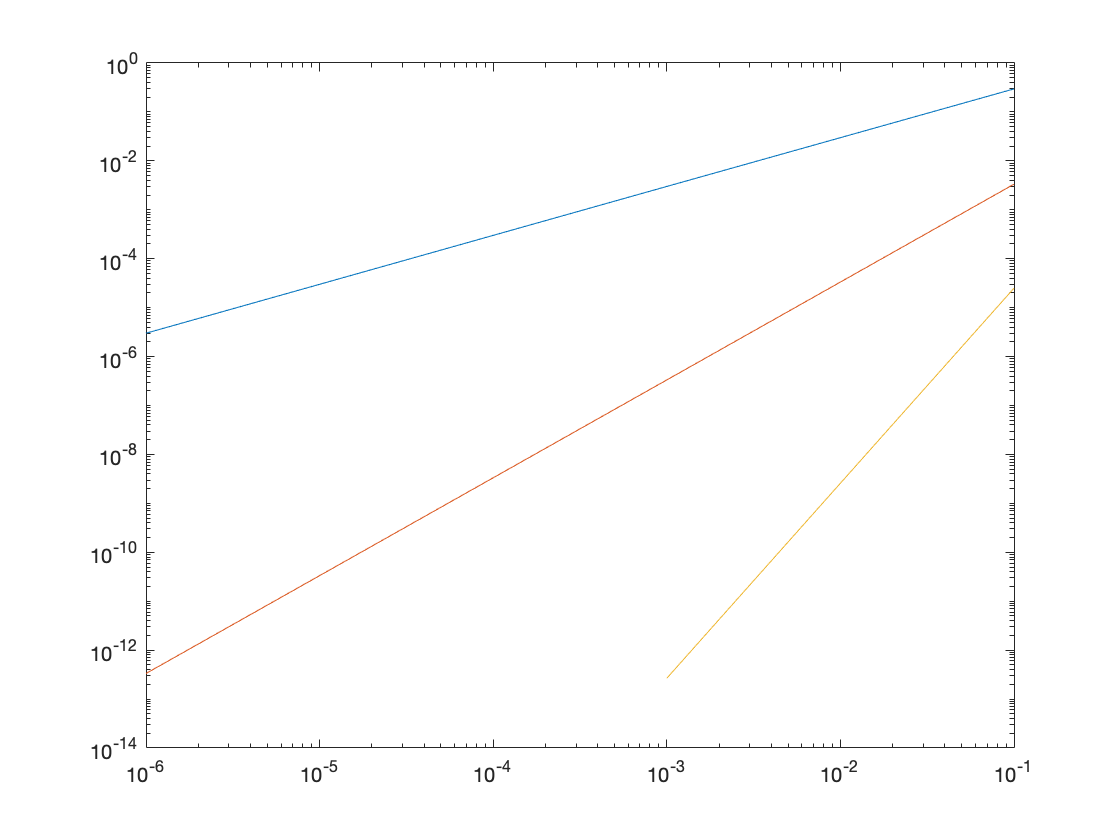



h = [h1 h2 h3];
errFD = abs([FD1 FD3 FD6] - 2);
errCD3 = abs([CD31 CD33 CD36] - 2);
errCD5 = abs([CD51 CD53 CD56] - 2);

err = [errFD errCD3 errCD5];

loglog(h,errFD);
hold on
loglog(h,errCD3);
hold on 
loglog(h,errCD5);
hold off

function fd = forward_difference(f, x0, h)
fd = (f(x0 + h) - f(x0)) ./ (h);
end

function cd1 = centered_difference(f, x0, h)
cd1 = (f(x0 + h) - f(x0 - h)) ./ (2 * h);
end

function cd2 = centered_difference2(f, x0, h)
cd2 = (-f(x0 + 2*h) + 8*f(x0 + h) - 8*f(x0 - h) + f(x0 - 2*h)) ./ (12 * h);
end